clear all;
filelist = ["data_04-Mar-2025_10.mat", 
"data_21-Mar-2025_10 motor0 19 to 31 rads.mat",
"data_21-Mar-2025_20 motor0 1v.mat",
"data_21-Mar-2025_20 motor0 31 to 40 rads 1.5v.mat"];
Ts = 1/500;
do_plots = false;
tableofData = [];
idObj=false;
for exp_id = 1:4
    file = "lab3/data/motor0/" + filelist(exp_id);
    load(file,"data");
    if do_plots
        smartPlotEncVoltage(data,filelist(exp_id),false);
    end
    
    fs=500;
    ts = 1/fs;
    
    motorID = 0;
    
    voltages_A = [1 1 1 1.5];
    voltage_A = voltages_A(exp_id);
    time = data(1,:);
    y = data(2+motorID,:)*pi/2048;
    u = data(4+motorID,:);
    % sweepanalysis assumes that the u has Amplitude 1
    om = data(6,:);
    
    
    slices = sliceTimeSeries(time,om);
    
    
    % wrong_exp = [ 0 5.5 13 17.5 18 20];
    
    maskOpts = detectImportOptions("lab3/data/motor0/experiment_mask_"+exp_id+".csv");
    mask = readtable("lab3/data/motor0/experiment_mask_"+exp_id+".csv",maskOpts);
    
    
    % for i = 2:2
    for i = 1:size(slices,2)
        omega = slices{i}.f;
        % k = find(wrong_exp==omega);
    if mask.enable(i) % it's one of the wrong experiments
        focus = slices{i};
    
        t_start_idx = time2index(focus.t_start+mask.t_start(i));
        t_end_idx = time2index(focus.t_end-mask.t_end(i));
       
    
        t_focus= time(t_start_idx:t_end_idx);
        om_focus= om(t_start_idx:t_end_idx);
        y_focus= y(t_start_idx:t_end_idx);
        u_focus= u(t_start_idx:t_end_idx);
        
        
        % [dataDD] = SweepAnalysisMI(t_focus,u_focus, y_focus,data,to_merge);
        

        if idObj == false
            [dataDD] = SweepAnalysisMI(t_focus,u_focus, y_focus,false,false);
            idObj = true;
        else
            [dataDD] = SweepAnalysisMI(t_focus,u_focus, y_focus,dataDD,true);
        end

        

    else
        continue
    end
    end
   

end



% Details about Estimation Data    
 % Import   dataDD                 
                                   
% Transfer function estimation     
 Options = tfestOptions;           
 Options.Display = 'on';           
 Options.EnforceStability = true;  
                                   
 tf2 = tfest(dataDD, 2, 0, Options);
 





cnc_params
P0 = P_ext(1);
mu0 = mu_ext(1);
P1 = P_ext(2);
mu1 = mu_ext(2);
tfours= tf(-mu0,[1/P0 1 0]);

zpk(tf2)


ans =
 
  From input "u1" to output "y1":
         -36.835
  ---------------------
  (s+25.95) (s+0.01539)
 
Continuous-time zero/pole/gain model.
Model Properties


zpk(tfours)


ans =
 
    -36.084
  -----------
  s (s+24.92)
 
Continuous-time zero/pole/gain model.
Model Properties


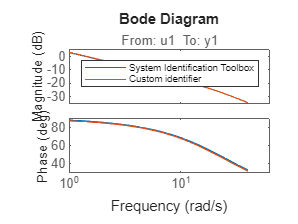


figure
bodeplot(tf2,{1,40})
hold on
bodeplot(tfours,{1,40})
hold off
legend(["System Identification Toolbox","Custom identifier"])

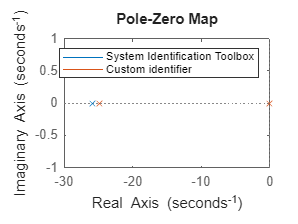




figure
pzmap(tf2)
hold on
pzmap(tfours)
hold off
legend(["System Identification Toolbox","Custom identifier"])

% Validation

filelistStep = ["data_04-Mar-2025_10.mat","data_04-Mar-2025_14-46-39.mat","data_04-Mar-2025_14-48-35.mat","data_04-Mar-2025_14-49-36.mat","data_04-Mar-2025_15-02-19.mat","data_04-Mar-2025_15-04-28.mat","data_04-Mar-2025_15-06-09.mat","data_04-Mar-2025_15-07-04.mat","data_04-Mar-2025_15-13-13.mat","data_04-Mar-2025_15-16-08.mat","data_04-Mar-2025_15-27-48.mat","data_04-Mar-2025_15-29-27.mat","data_04-Mar-2025_15-30-56.mat","data_04-Mar-2025_15-31-20.mat","data_04-Mar-2025_15-33-26.mat","data_04-Mar-2025_15-34-00.mat","data_04-Mar-2025_15-37-14.mat","data_04-Mar-2025_15-39-43.mat","data_04-Mar-2025_15-42-28.mat","data_04-Mar-2025_15-43-46.mat","data_04-Mar-2025_15-47-42.mat","data_04-Mar-2025_15-49-10.mat","data_04-Mar-2025_15-51-30.mat","data_04-Mar-2025_15-52-22.mat","data_04-Mar-2025_15-54-09.mat","data_04-Mar-2025_15-57-04.mat","data_04-Mar-2025_16-08-14.mat","data_04-Mar-2025_16-11-22.mat","data_04-Mar-2025_16-14-18.mat","data_04-Mar-2025_16-16-56.mat","data_04-Mar-2025_16-18-18.mat","data_04-Mar-2025_16-21-30.mat","data_04-Mar-2025_16-24-24.mat","data_04-Mar-2025_16-29-52.mat","data_04-Mar-2025_16-55-40.mat","data_04-Mar-2025_17-24-37.mat","data_04-Mar-2025_17-40-31.mat","data_04-Mar-2025_17-41-21.mat","data_04-Mar-2025_17-43-22.mat","data_04-Mar-2025_17-50-09.mat","data_04-Mar-2025_17-51-54.mat","data_04-Mar-2025_17-54-59.mat","data_04-Mar-2025_17-57-30.mat","data_04-Mar-2025_17-57-53.mat","data_04-Mar-2025_18-00-51.mat","data_04-Mar-2025_18-01-13.mat","data_04-Mar-2025_18-03-09.mat","data_04-Mar-2025_18-06-22.mat","data_04-Mar-2025_18-07-09.mat","data_04-Mar-2025_18-09-15.mat","data_04-Mar-2025_18-10-36.mat","data_04-Mar-2025_18-11-39.mat","data_04-Mar-2025_18-12-13.mat","data_04-Mar-2025_18-13-24.mat","data_04-Mar-2025_18-14-40.mat","data_04-Mar-2025_18-15-39.mat","data_04-Mar-2025_18-16-46.mat","data_04-Mar-2025_18-17-52.mat","data_04-Mar-2025_18-18-49.mat"];
file_index = [ 47 48 49 50 51 52 53 54 55 56 57 58];
for i = 1:size(file_index,2)
    t_samp = 0.002;
    n_exp = file_index(i);
    load("lab1/data/"+filelistStep(n_exp),"data");
end


function idx = time2index(time)
idx = floor(time/0.002)+1;
end

function [freqs, phases, gain, phase_dels] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    phase_dels = [];
    for i = 1:size(slices,2)
    freqs(i) = slices{i}.f;
    phases(i) = slices{i}.phase;
    gain(i) = slices{i}.gain;
    phase_dels(i) = slices{i}.phase_del;
    end

end